# Petri Dish - Finite Differences

clear variables

## Governing equation 

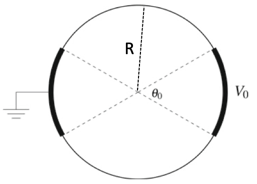


$$\frac{1}{r}{\frac{\partial \phi}{\partial r}\;+\frac{\partial^2 \phi}{\partial r^2 }\;+\frac{1}{r^2}{\frac{\partial^2 \phi}{\partial \theta^2 }\;=0$$


## Finite differences implementation


$$
\Delta r = \frac{R} {N} \;\;\;\; \Delta \theta=\frac{\pi}{M} \\
r_i=(i-1)\,\Delta r \;\;\;\; i=1\, ... \, N+1 \\
\theta_j=(j-1)\,\Delta \theta \;\;\;\; j=1\, ... \, M+1$$


Discretized PDE:


$$\frac{1}{r_i}\,\frac{\phi_{i+1,j}-\phi_{i,j}}{\Delta r}+\frac{\phi_{i+1,j}-2\,\phi_{i,j}+\phi_{i-1,j}}{\Delta r^2}+\frac{1}{{r_i}^2 }\,\frac{\phi_{i,j+1}-2\,\phi_{i,j}+\phi_{i,j-1}}{\Delta \theta^2}=0$$


Note: the discretized PDE is undefined for $r=0
$ so it is valid for  $i>1$. We cannot use this approximation at the center of the domain (for $r_i=0$ when $i=1$). This is due to the choice of polar coordinates and not to a real discontinuity in the problem. We will then approximate the potential at the center of the domain by considering the mean value of the surrounding nodes. 


$$\phi_{1,j}=\frac{1}{M+1}\sum_{j=1}^{M+1}{\phi_{2,j}}$$


Including in the discretized PDE the definition of $\Delta r$ and $\Delta \theta$:


$$\frac{1}{(i-1)\,\Delta r}\,\frac{\phi_{i+1,j}-\phi_{i,j}}{\Delta r}+\frac{\phi_{i+1,j}-2\,\phi_{i,j}+\phi_{i-1,j}}{\Delta r^2}+\frac{1}{(i-1)^2\,\Delta r^2}\,\frac{\phi_{i,j+1}-2\,\phi_{i,j}+\phi_{i,j-1}}{\Delta \theta^2}=0
$$


Multiplying by $(i-1)^2\,\Delta r^2\, \Delta \theta^2$:


$$\left({\phi_{i+1,j}-\phi_{i,j}} \right)\,(i-1)\, \Delta \theta^2+\left({\phi_{i+1,j}-2\,\phi_{i,j}+\phi_{i-1,j}} \right )(i-1)^2\, \Delta \theta^2+\left({\phi_{i,j+1}-2\,\phi_{i,j}+\phi_{i,j-1}} \right )=0$$


Collection of nodal variables:


$$\left( (i-1)^2\,\Delta \theta^2\;+ (i-1)\,\Delta \theta^2 \right) \, \phi_{i+1,j}\;+\left( (i-1)^2\,\Delta \theta^2 \right) \, \phi_{i-1,j}- \left( 2+(i-1)\,\Delta \theta^2\;+ 2\,(i-1)^2\,\Delta \theta^2 \right) \,\phi_{i,j}\;+\phi_{i,j+1}\;+\phi_{i,j-1}=0$$


Parametric form:


$$k_1 \, \phi_{i+1,j}\;+k_2 \, \phi_{i-1,j}\;+k_3\,\phi_{i,j}\;+\phi_{i,j+1}\;+\phi_{i,j-1}=0 $$


where:


$$c_1=(i-1)^2\,\Delta \theta^2 \\
c_2=(i-1)\,\Delta \theta^2 \\
k_1=c_1+c_2  \\
k_2=c_1 \\
k_3= -\left(2\,+2\,c_1 +c_2\;\right) \\$$


### Boundary conditions

#### Dish walls 

$\phi_{N+1,j}=V_0 \;\;\;\;\; \theta_j=(j-1)\,\Delta \theta \leq \frac{\theta_0}{2} $      Active electrode

$\phi_{N+1,j}=0 \;\;\;\;\; \theta_j=(j-1)\,\Delta \theta \ge \pi - \frac{\theta_0}{2} $     Ground electrode

$\phi_{N+1,j}=\phi_{N,j} \rightarrow \; \phi_{N+1,j}-\phi_{N,j}=0 \;\;\;\;\; \frac{\theta_0}{2} < \theta_j =(j-1)\,\Delta \theta< \pi - \frac{\theta_0}{2} 
$     Outside the electrodes

### Symmetry about the x-axis

 $\phi_{i,1} =\phi_{i,2} \rightarrow\;  \phi_{i,1} -\phi_{i,2}=0  $ if $\theta_i=0 $ $\rightarrow j=1$ $\forall i\ne1$

$\phi_{i,M+1} =\phi_{i,M} \rightarrow\; \phi_{i,M+1} -\phi_{i,M}=0$ if $\theta_i=\pi$ $\rightarrow j=M+1$ $\forall i\ne1$

### Center of the dish


$$r_i=0 \rightarrow i=1$$



$$\phi_{1,j} =\frac{1}{M+1}\sum_{j=1}^{M+1}\phi_{2,j} \rightarrow\;  ({M+1})\,\phi_{1,j} - \sum_{j=1}^{M+1}\phi_{2,j}  =0$$


### Implementation 

clear variables
close all
R=0.045; % radius m
theta_0=pi/3; %theta_0 radians
V0=2; %V0 Volts 
N=100; 
M=150; 
d_r=R/N; %radial step 
d_theta=pi/M; %angular step 
B=sparse((N+1)*(M+1),1); 
A=sparse((N+1)*(M+1),(N+1)*(M+1)); % A will contain mostly zero entries 
% and is therefore sparse. % Sparse matrices are highly advantageous 
% from a computational point of view because very large matrix systems 
% can be efficiently stored in computer memory and solved for.

for i=1:N+1 %radial index
    c1=(i-1)^2*d_theta^2;
    c2=(i-1)*d_theta^2;
    k1=c1+c2;
    k2=c1;
    k3=-(2+2*c1+c2);
    for j=1:M+1 %angular index
        h=(M+1)*(i-1)+j;
        if (i==1) %center of the dish
            A(h,h)=M+1;
            A(h,1+M+1:1+M+1+M)=-1; 
        elseif (i==N+1) %circular boundary
            theta=(j-1)*d_theta;
            if (theta <= theta_0/2) %active electrode 
                B(h)=V0;
                A(h,h)=1;
            elseif (theta >= pi-theta_0/2) %ground electrode
                A(h,h)=1; %B(index) is 0 by default
            else %electrical insulation
                A(h,h)=1;
                A(h,h-(M+1))=-1;
            end
        elseif (j==1) %x-axis (thetaj=0)
            A(h,h)=1;
            A(h,h+1)=-1;
        elseif (j==M+1) %x-axis (thetaj=pi)
            A(h,h)=1;
            A(h,h-1)=-1;
        else   %in the domain
            A(h,h)=k3;  %i,j -> h=(M+1)*(i-1)+j
            A(h,h-(M+1))=k2; %i-1,j  ->h-(M+1)
            A(h,h+(M+1))=k1; %i+1,j -> h+(M+1)
            A(h,(h+1))=1; %i,j+1 -> h+1
            A(h,(h-1))=1; %i,j-1 -> h-1
        end
    end
end
% to see A -> A_=full(A);
%solve the system
%A=full(A);
%B=full(B);
tic
Y=A\B;
toc

Elapsed time is 0.091171 seconds.


V=reshape(Y,M+1,N+1); %theta->col r->row 
%Matlab help: "reshape(X,M,N) returns the M-by-N
% matrix whose elements are taken columnwise from X"

## Results: electric potential 

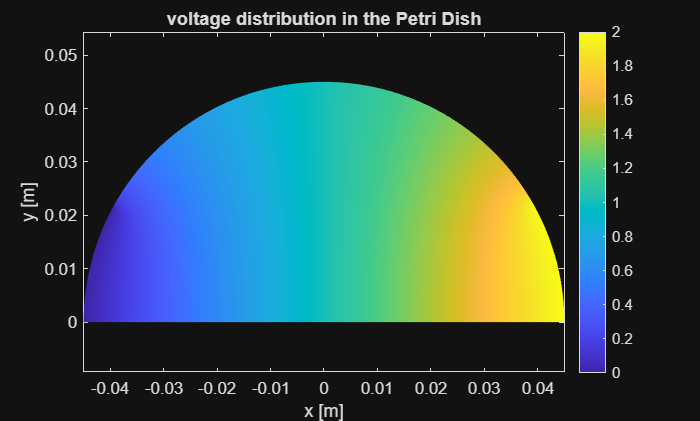

[RR, th]=meshgrid(0:d_r:R,0:d_theta:pi);
%Matlab help: Cartesian rectangular grid in 2-D or 3-D 
% [X,Y] = meshgrid(x,y) returns 2-D grid coordinates based on the
% coordinates contained in vectors x and y. 
% X is a matrix where each row is a copy of x, and Y is a matrix where each column is a copy of y. 
% The grid represented by the coordinates X and Y has length(y) rows and length(x) columns.
XX=RR.*cos(th);
YY=RR.*sin(th);
pcolor(XX,YY,V); colorbar; axis('equal'); shading('interp'); 
xlabel('x [m]')
ylabel('y [m]')
title('voltage distribution in the Petri Dish')

## Electric field


$$\mathbf{E}=- \nabla\phi =-  \;\left( \begin{array}{c}
\frac{\partial \phi}{\partial x } \\
\frac{\partial \phi}{\partial y }  \\
 \end{array} \right) 
$$


**E** magnitude: 


$$\left|\mathbf{E}\right|=  \sqrt {
\left ( \frac{\partial \phi}{\partial x } \right)^2  +\left ( 
\frac{\partial \phi}{\partial y } \right)^2 
 \end{array} \right) }
$$



$$\frac{\partial \phi}{\partial x }=\frac{x}{r}\,\frac{\partial \phi}{\partial r} -\frac{y}{r^2} \frac{\partial \phi}{\partial \theta }} $$



$$\frac{\partial \phi}{\partial y }=\frac{y}{r}\,\frac{\partial \phi}{\partial r}+\frac{x}{r^2 }\,\frac{\partial \phi}{\partial \theta } $$


syms r theta phi(r,theta) sigma
x=r*cos(theta)

$$x = r\,\cos\left(\theta \right)$$

y=r*sin(theta)

$$y = r\,\sin\left(\theta \right)$$

dphix=(x*diff(phi(r, theta), r))/r - (y*diff(phi(r, theta), theta))/r^2

$$dphix = \cos\left(\theta \right)\,\frac{\partial }{\partial r}\varphi \left(r,\theta \right)-\frac{\sin\left(\theta \right)\,\frac{\partial }{\partial \theta }\varphi \left(r,\theta \right)}{r}$$

dphiy=(y*diff(phi(r, theta), r))/r + (x*diff(phi(r, theta), theta))/r^2

$$dphiy = \sin\left(\theta \right)\,\frac{\partial }{\partial r}\varphi \left(r,\theta \right)+\frac{\cos\left(\theta \right)\,\frac{\partial }{\partial \theta }\varphi \left(r,\theta \right)}{r}$$

E=(dphix^2+dphiy^2)^0.5

$$E = \sqrt{{\left(\sin\left(\theta \right)\,\frac{\partial }{\partial r}\varphi \left(r,\theta \right)+\frac{\cos\left(\theta \right)\,\frac{\partial }{\partial \theta }\varphi \left(r,\theta \right)}{r}\right)}^{2}+{\left(\cos\left(\theta \right)\,\frac{\partial }{\partial r}\varphi \left(r,\theta \right)-\frac{\sin\left(\theta \right)\,\frac{\partial }{\partial \theta }\varphi \left(r,\theta \right)}{r}\right)}^{2}}$$

E=simplify((dphix^2+dphiy^2)^0.5,"IgnoreAnalyticConstraints",true)

$$E = \frac{\sqrt{r^{2}\,{\left(\frac{\partial }{\partial r}\varphi \left(r,\theta \right)\right)}^{2}+{\left(\frac{\partial }{\partial \theta }\varphi \left(r,\theta \right)\right)}^{2}}}{r}$$

To calculate the magnitude of the electric field in the center of the dish, we exploit the symmetry about the x-axis: E is parallel to the x-axis at the center:


$$\mathbf{E}_c=-  \;\left( \begin{array}{c}
\frac{\partial \phi}{\partial x } \biggr|  _{x=0, y=0} \\
0   \\
 \end{array} \right)  \\
\left|{\mathbf{E}}_c\right|=  \left| \frac{\partial \phi}{\partial x}\biggr|  _{x=0, y=0} \, = \,  \left|\frac{\partial \phi}{\partial r}\biggr|  _{r=0, \theta=0} $$


We define a scalar function which is 1 when the electric field is within 10% of variation)


$$\Gamma_A=  
\begin{cases} 1 &0.9\leq\,\frac{E}{E_c}\leq1.1  \\
0 &otherwise
\end{cases}
$$


The area for which the electric field magnitude is +- 10% of the value in the center is 


$$Area=\int_{0}^{\pi}\int_{0}^{R}\Gamma_A(r,\theta)r\,drd\theta$$


We calculate the area against the electrode angle $\theta_0
$ (PetriDishUniformField.m) 